## Experimento 2 - Codificador LPC

#### Bruno Hashimoto - 10715628

#### Guilherme Fernandes - 10297272

### 4.1

% leitura do sinal
[sinal, fs] = audioread('antarctica.wav');
trecho = sinal(200:439, 1);

[ak, ~] = lpc(trecho.*hamming(240), 10);
ak

ak =     1.0000   -0.9688   -0.2256    0.1966    0.4494   -0.0673   -0.5598    0.1325    0.5139    0.0094   -0.2692


Como esperado, o vetor ak apresenta 11 elementos, sendo ak(0) = 1 e o restante, os coeficientes do filtro.

### 4.2

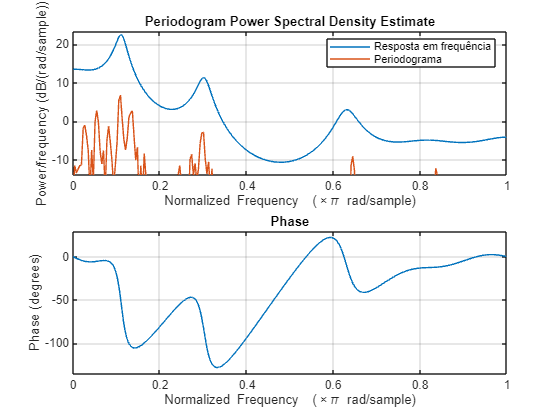

G = 1;
freqz(G, ak, 512); 
hold on;
periodogram(trecho,[],512); % 4.3
legend('Resposta em frequência', 'Periodograma')
hold off;

Como esperado, a resposta em frequência do modelo LPC (curva em laranja) acompanha a envoltória da transformada do sinal (curva em azul). 

### 4.4

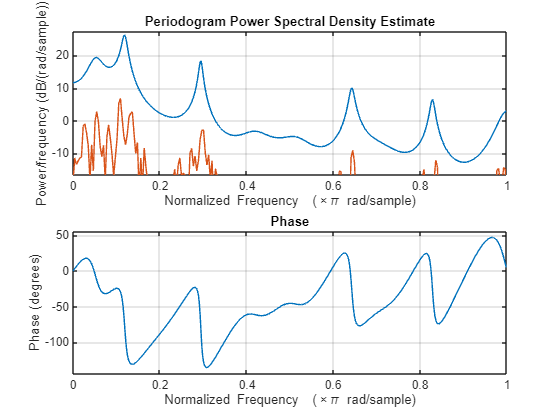

[ak, ~] = lpc(trecho.*hamming(240), 20);
figure;
freqz(G, ak, 512);
hold on;
periodogram(trecho, [], 512);

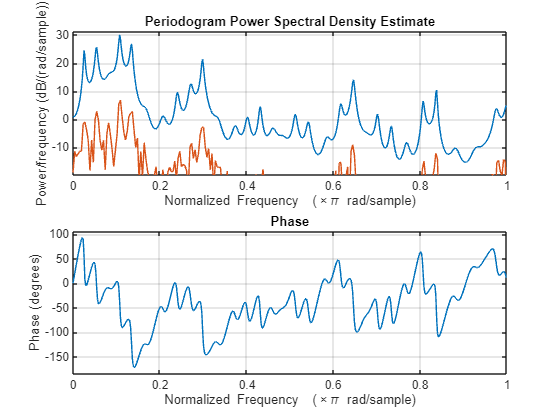

[ak, ~] = lpc(trecho.*hamming(240), 40);
figure;
freqz(G, ak, 512);
hold on;
periodogram(trecho, [], 512);

[ak, ~] = lpc(trecho.*hamming(240), 80);
figure;
freqz(G, ak, 512);
hold on;
periodogram(trecho, [], 512);

Aumentando-se a ordem do modelo LPC o modelo começa a reproduzir os detalhes do periodograma, o que fica mais visível com a ordem de 80 do LPC.

###  4.5 Estimação de pitch usando Yaapt

plot_fig = true;
pitch = yaapt(sinal, fs, 1, [], plot_fig, 1);
pitch = [0 pitch]

### **4.6 Estimação de sinal usando pitch**

N = length(sinal);
sinal_gerado = [];
N_amostras = 80;
N_trecho = 280;
i = 0;
for start=1:N_amostras:(N-N_trecho+N_amostras)
    % 6.a
    i = i + 1;
    if start + N_trecho - 1 > length(sinal) % start+280 > 11201
        trecho = sinal(start:end, 1);
        [ak, sig2] = lpc(trecho.*hamming(length(trecho)), 10);
    else
        trecho = sinal(start:(start+N_trecho-1), 1);
        [ak, sig2] = lpc(trecho.*hamming(N_trecho), 10);
    end

    % 6.b
    if pitch(i) > 0
        G = sqrt(pitch(i)*sig2); % 6.d
        %1. gerar uma sequencia de pulsos
        T = 1/pitch(i); % s
        s = zeros(N_amostras, 1); %0:10ms
        s(1) = 1;
        fator = 10e-3/N_amostras; 
        soma = 0;
        for j=1:N_amostras
            if soma >= T
                s(j) = 1;
                soma = 0;
            end
            soma = soma + fator;
        end
    else
        G = sqrt(sig2); % 6.d
        %2. gere um trecho de ruido com 80 amostras usando randn
        s = randn(N_amostras, 1);
    end
    
    trechosint = filter(G, ak, s);
    sinal_gerado = [sinal_gerado; trechosint];
end

### 4.6 Com parâmetros quantizados

%% 
N = length(sinal);
sinal_gerado_quant = [];
N_amostras = 80;
N_trecho = 280;
i = 0;
Ba = 7;
Bg = 5;
for start=1:N_amostras:(N-N_trecho+N_amostras)
    % 6.a
    i = i + 1;
    if start + N_trecho - 1 > length(sinal) % start+280 > 11201
        trecho = sinal(start:end, 1);
        [ak, sig2] = lpc(trecho.*hamming(length(trecho)), 10);
    else
        trecho = sinal(start:(start+N_trecho-1), 1);
        [ak, sig2] = lpc(trecho.*hamming(N_trecho), 10);
    end
    ak = quantize3(ak,Ba);

    % 6.b
    Tp = quantize3(pitch(i), Bg);
    if Tp > 0
        G = quantize3(sqrt(Tp*sig2), Bg);
        
        %1. gerar uma sequencia de pulsos
        fp = 1/Tp; % s - freq pitch
        s = zeros(N_amostras, 1); %0:10ms
        s(1) = 1;
        fator = 10e-3/N_amostras; 
        soma = 0;
        for j=1:N_amostras
            if soma >= fp
                s(j) = 1;
                soma = 0;
            end
            soma = soma + fator;
        end
    else
        G = quantize3(sqrt(sig2), Bg);
        %2. gere um trecho de ruido com 80 amostras usando randn
        s = randn(N_amostras, 1);
    end
    
    trechosint = filter(G, ak, s);
    sinal_gerado_quant = [sinal_gerado_quant; trechosint];
end

Plotando os sinas gerados

figure;
plot(sinal_gerado)
hold on; grid on;
plot(sinal_gerado_quant);
legend('Sinal Sintetizado', 'Sinal Sintetizado Quantizado');